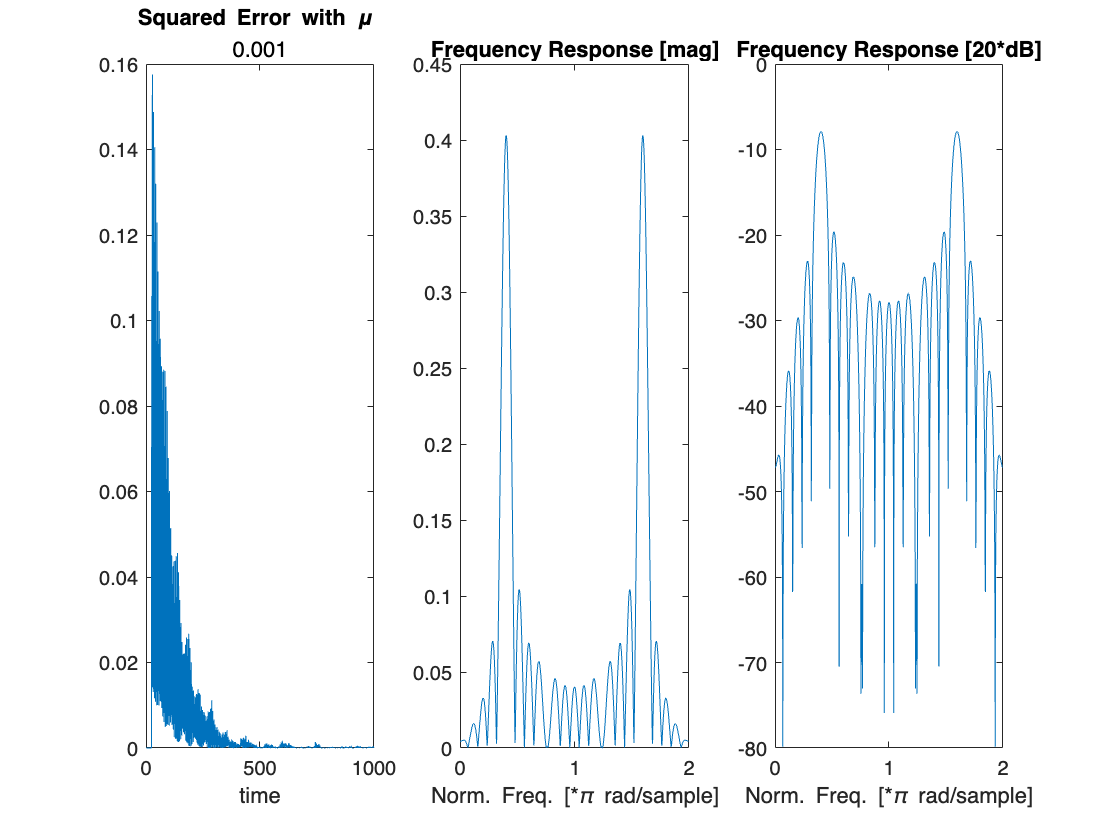

% Adaptive Filter (Step 1/2)
clf()

M = 25;      % adaptive filter length
L = 1000;      % number of samples
mu =  0.001;  % learning rate
N = L + (M-1);   % sequence length

y_out = zeros(1,L); % initialize output
err_out = zeros(1,L);  % initialize error
w = zeros(M,1);  % initialize weights


% generate x and d
a = 0.1;  % Noise coefficent
x = cos(2*pi*0.2*(0:(N-1))) + cos(2*pi*0.38*(0:(N-1)))+a*randn(1,N);
d = 0.4*cos(2*pi*0.2*(0:(N-1)) + pi/5);

% adaptive filter block
for idx = M:L

    % calculate y from current weights
    xn = transpose(x(idx:-1:idx-(M-1)));
    yn = transpose(w)*xn;
    y_out(idx) = yn;

    % calculate error
    en = d(idx) - yn;
    err_out(idx) = en;

    % calculate new weights
    w = w + (mu*en)*xn;
end

% Define time and frequency vector
t_vec = 1:L;
dF = (2)/N;
fv = (0:N-1)*dF;

% Generate plots of squared error, frequency response
figure()
subplot(1,3,1)
plot(t_vec, err_out.^2)
title("Squared Error with \mu ",num2str(mu))
xlabel('time')

subplot(1,3,2)
H = freqz(transpose(w), 1, N, 'whole');
plot(fv, abs(H))
title("Frequency Response [mag]")
xlabel("Norm. Freq. [*\pi rad/sample]")

subplot(1,3,3)
plot(fv, 20*log10(abs(H)))
title("Frequency Response [20*dB]")
xlabel("Norm. Freq. [*\pi rad/sample]")

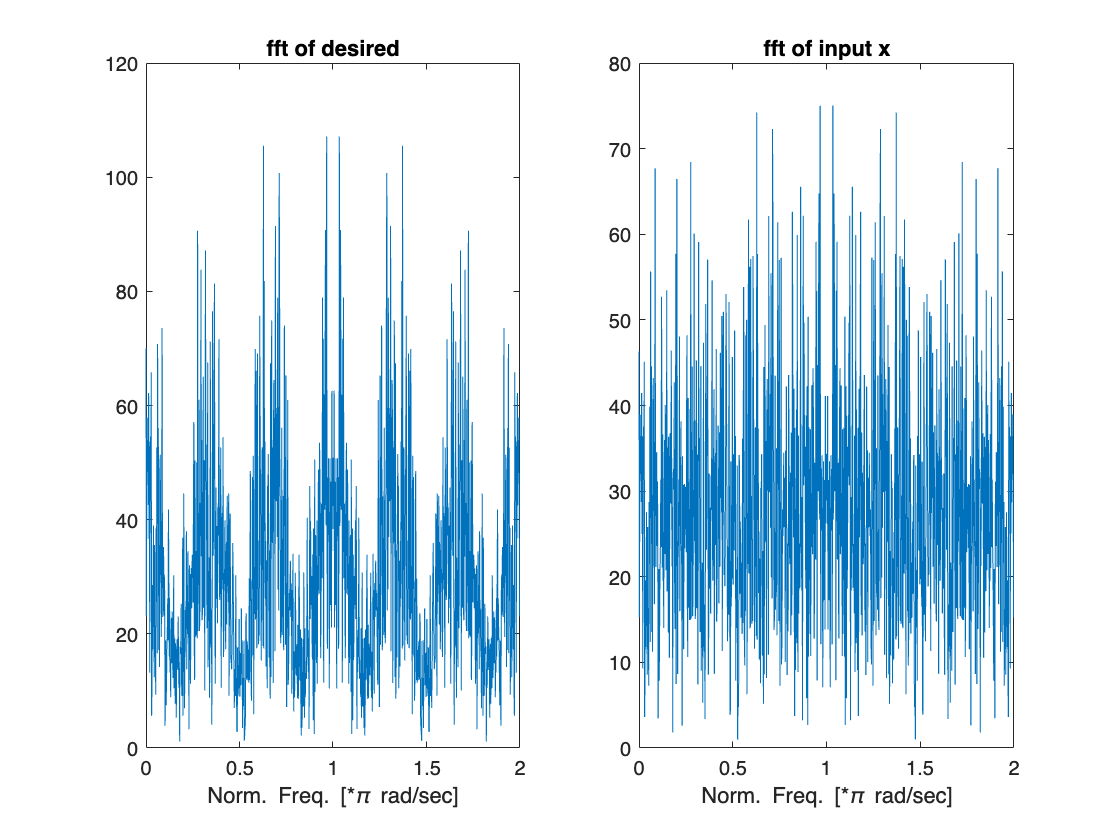

% Adaptive Filter (Step 3)
clf()
clear all

M = 25;      % adaptive filter length
L = 1000;      % number of samples
mu = 0.01;  % learning rate
N = L + (M-1);   % sequence length

y_out = zeros(1,L); % initialize output
err_out = zeros(1,L);  % initialize error
w = zeros(M,1);  % initialize weights


% generate x and d
h = [1, 0, 0, 0, 0, 0, 0.5];
x = randn(1,L);
x_unk = conv(h,x);
d = x_unk(length(h):end); % make d the same length as x

% adaptive filter block
for idx = M:L

    % calculate y from current weights
    xn = transpose(x(idx:-1:idx-(M-1)));
    yn = transpose(w)*xn;
    y_out(idx) = yn;

    % calculate error
    en = d(idx) - yn;
    err_out(idx) = en;

    % calculate new weights
    w = w + (mu*en)*xn;
end

% Define time and frequency vector
t_vec = 1:L;
dF = (2)/L;
fv = (0:L-1)*dF;

% Generate fft of desired, fft of adaptive filter
figure()
subplot(1,2,1)
D = fft(d);
plot(fv, abs(D))
title("fft of desired")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(1,2,2)
X = fft(x);
plot(fv, abs(X))
title("fft of input x")
xlabel("Norm. Freq. [*\pi rad/sec]")

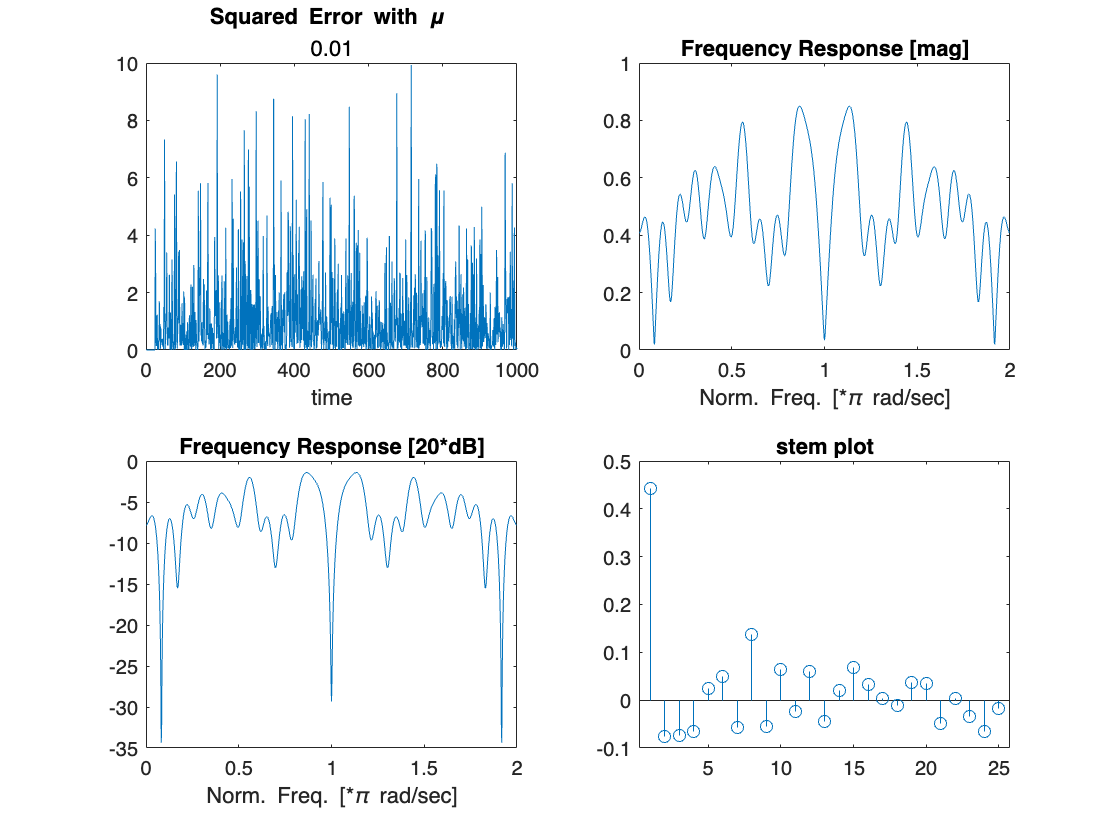

% Generate plots of squared error, frequency response, stem plot
figure()
subplot(2,2,1)
plot(t_vec, err_out.^2)
title("Squared Error with \mu ",num2str(mu))
xlabel('time')

subplot(2,2,2)
H = freqz(transpose(w), 1, L, 'whole');
plot(fv, abs(H))
title("Frequency Response [mag]")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(2,2,3)
plot(fv, 20*log10(abs(H)))
title("Frequency Response [20*dB]")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(2,2,4)
stem(w)
title("stem plot")

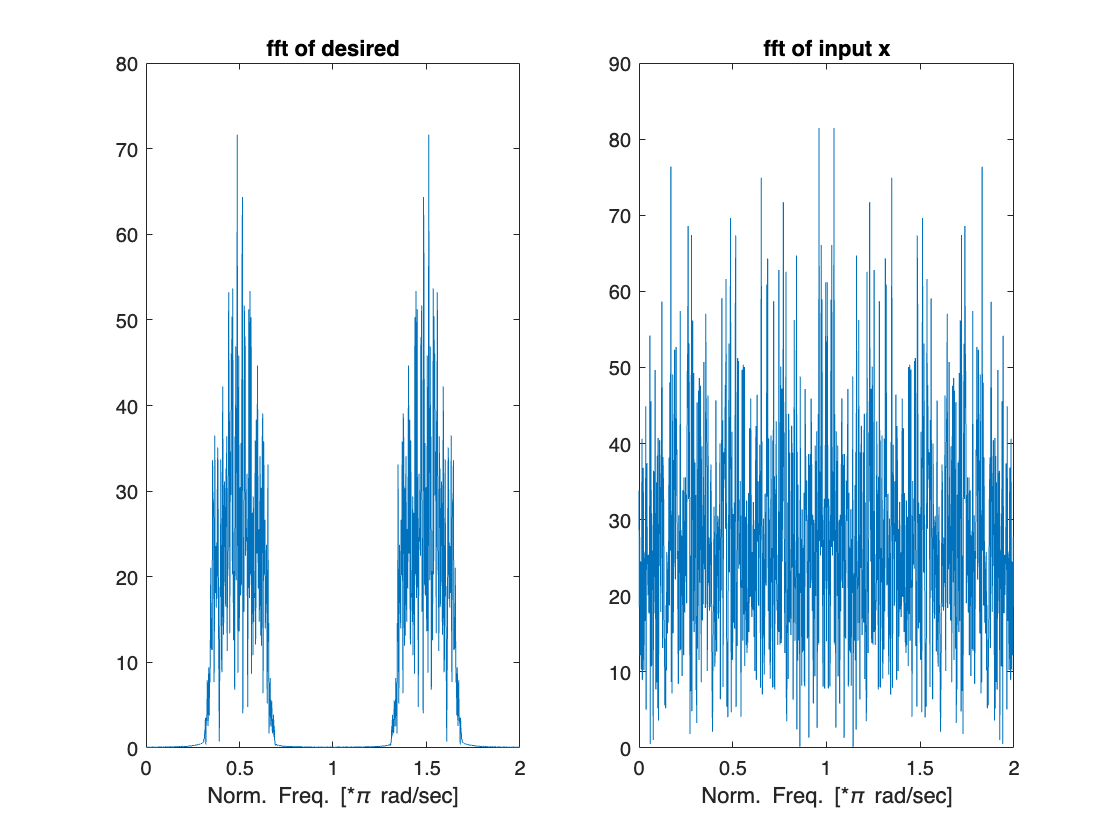

% Adaptive Filter (Step 3)
clf()
clear all

M = 64;      % adaptive filter length
L = 1000;      % number of samples
mu = 0.01;  % learning rate
N = L + (M-1);   % sequence length

y_out = zeros(1,L); % initialize output
err_out = zeros(1,L);  % initialize error
w = zeros(M,1);  % initialize weights


% generate x and d
f_pm = [0, 1200, 1600, 2400, 2800, 4000]/4000;
a_pm = [0,0,1,1,0,0]; % band pass
n_pm = 64;
b_pm = firpm(n_pm, f_pm, a_pm);
x = randn(1,L); % create x input for both filters
x_unk = conv(b_pm, x);
d = x_unk(1: end- length(b_pm)+1); % make d the same length as x


% adaptive filter block
for idx = M:L

    % calculate y from current weights
    xn = transpose(x(idx:-1:idx-(M-1)));
    yn = transpose(w)*xn;
    y_out(idx) = yn;

    % calculate error
    en = d(idx) - yn;
    err_out(idx) = en;

    % calculate new weights
    w = w + (mu*en)*xn;
end

% Define time and frequency vector
t_vec = 1:L;
dF = (2)/L;
fv = (0:L-1)*dF;



% Generate fft of desired, fft of adaptive filter
figure()
subplot(1,2,1)
D = fft(d);
plot(fv, abs(D))
title("fft of desired")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(1,2,2)
X = fft(x);
plot(fv, abs(X))
title("fft of input x")
xlabel("Norm. Freq. [*\pi rad/sec]")

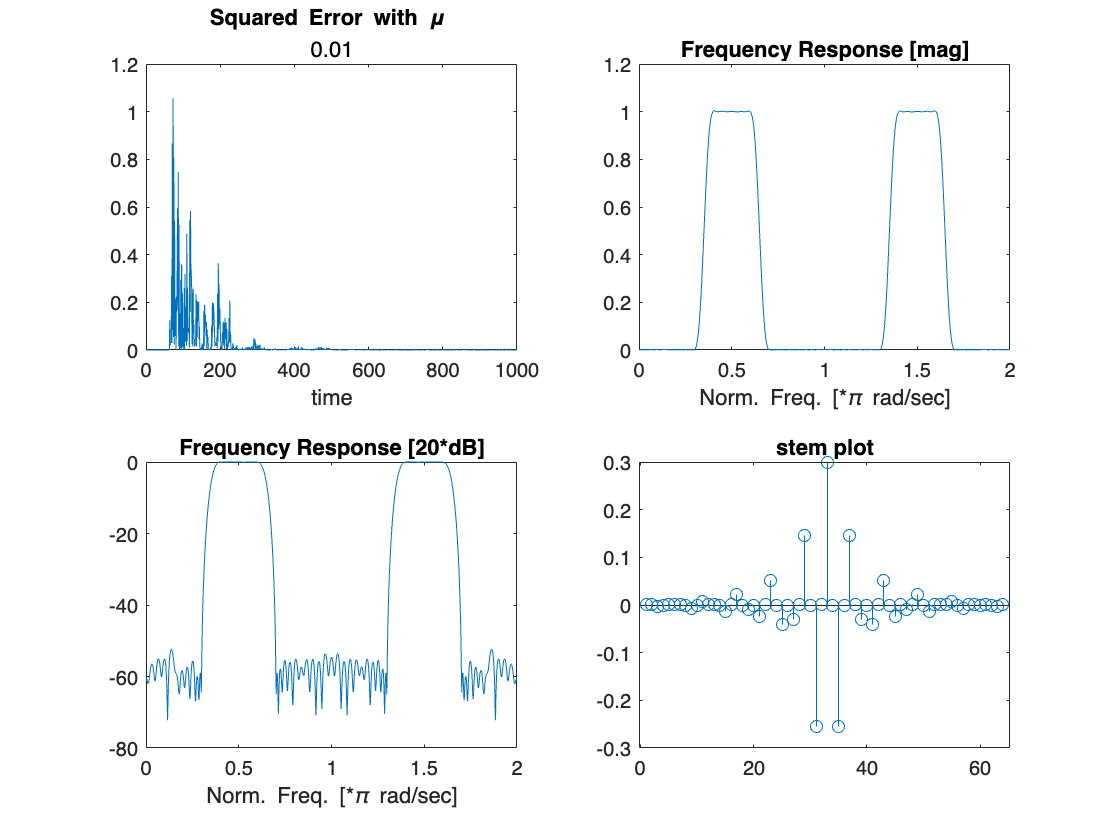




% Generate plots of squared error, frequency response, stem plot
figure()
subplot(2,2,1)
plot(t_vec, err_out.^2)
title("Squared Error with \mu ",num2str(mu))
xlabel('time')

subplot(2,2,2)
H = freqz(transpose(w), 1, L, 'whole');
plot(fv, abs(H))
title("Frequency Response [mag]")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(2,2,3)
plot(fv, 20*log10(abs(H)))
title("Frequency Response [20*dB]")
xlabel("Norm. Freq. [*\pi rad/sec]")

subplot(2,2,4)
stem(w)
title("stem plot")

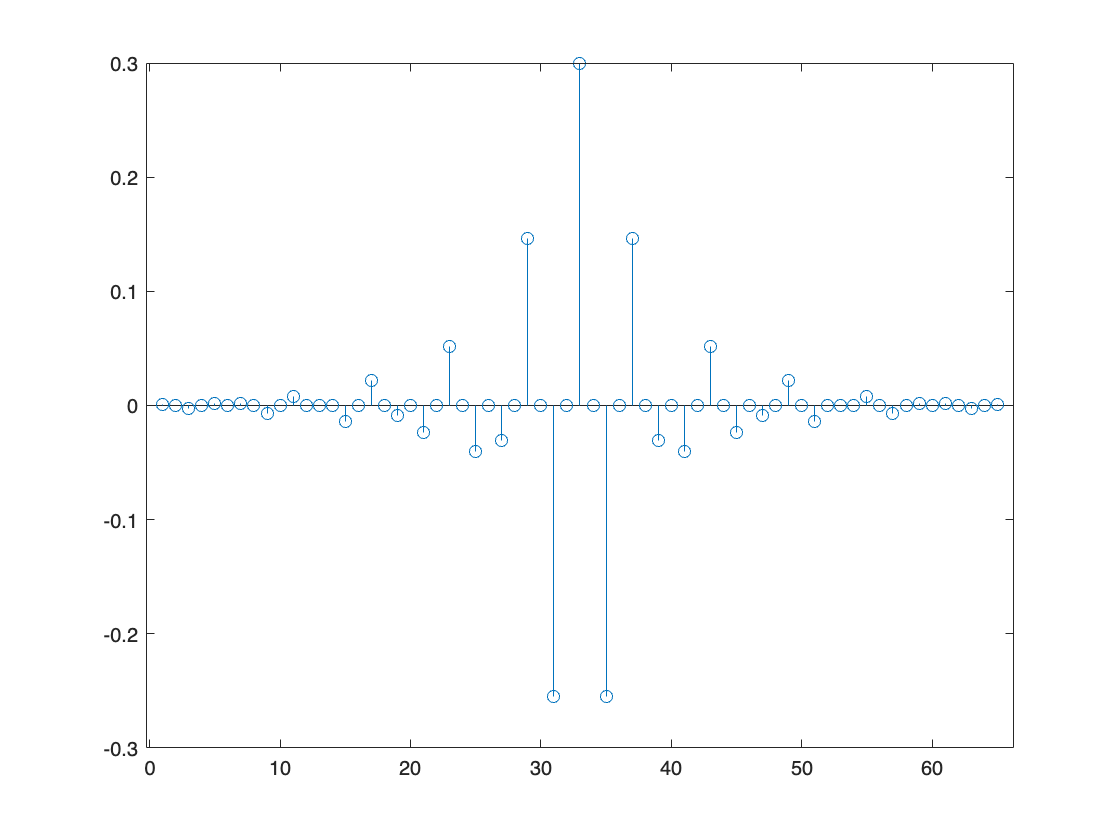

figure()
stem(b_pm)